# Singular values

## Minimum phase:

run("quadtank_minphase.m");


 Operating point search report:
---------------------------------

 Operating point search report for the Model nlQuadtank.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) nlQuadtank/h1_state
      x:          12.1      dx:     -2.97e-08 (0)
(2.) nlQuadtank/h2_state
      x:          12.6      dx:     -5.19e-08 (0)
(3.) nlQuadtank/h3_state
      x:          2.51      dx:      1.02e-07 (0)
(4.) nlQuadtank/h4_state1
      x:          2.48      dx:      9.35e-08 (0)

Inputs: 
----------
(1.) nlQuadtan

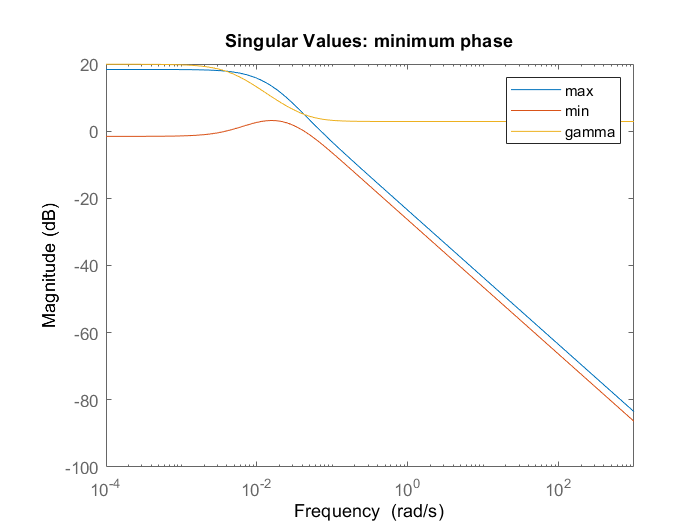

A =sys_mp.A;
B =sys_mp.B;
C =sys_mp.C;
D =sys_mp.D;
s = tf('s');
G_mp = C*inv(s*eye(length(A)) - A)*B;

w = logspace(-4,3,100);
for i = 1:length(w)
    Gf = freqresp(G_mp, w(i));
    n = min(size(Gf));
    [~,S,~] = svd(Gf); 
    s_max_w(i) = S(1,1);
    s_min_w(i) = S(n,n);
    gamma_w(i) = s_max_w(i)/s_min_w(i);
end
s_max = frd(s_max_w,w);
s_min = frd(s_min_w,w);
gamma = frd(gamma_w,w);
bodemag(s_max, s_min, gamma)
legend('max','min','gamma')
title('Singular Values: minimum phase')

## Non minimum phase

run("quadtank_nonminphase.m");


 Operating point search report:
---------------------------------

 Operating point search report for the Model nlQuadtank.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) nlQuadtank/h1_state
      x:          6.79      dx:     -2.95e-09 (0)
(2.) nlQuadtank/h2_state
      x:          8.78      dx:     -1.09e-08 (0)
(3.) nlQuadtank/h3_state
      x:          2.97      dx:      5.05e-09 (0)
(4.) nlQuadtank/h4_state1
      x:          4.17      dx:       1.3e-08 (0)

Inputs: 
----------
(1.) nlQuadtan

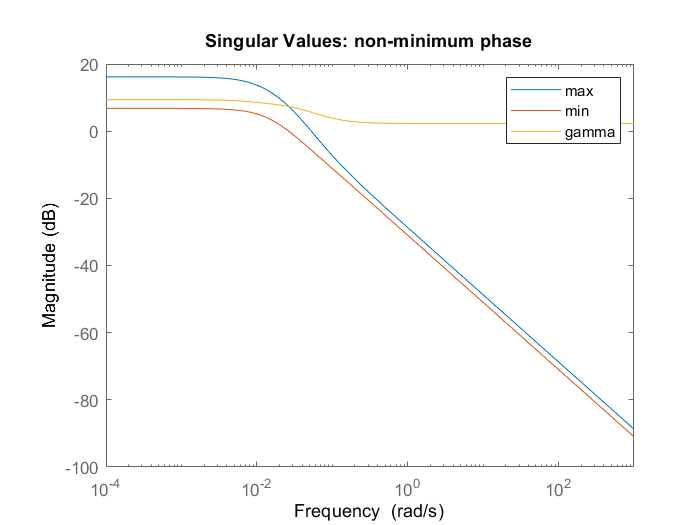

G_np = tf(sys_np);
w = logspace(-4,3,100);
for i = 1:length(w)
    Gf = freqresp(G_np, w(i));
    n = min(size(Gf));
    [~,S,~] = svd(Gf); 
    s_max_w(i) = S(1,1);
    s_min_w(i) = S(n,n);
    gamma_w(i) = s_max_w(i)/s_min_w(i);
end
s_max = frd(s_max_w,w);
s_min = frd(s_min_w,w);
gamma = frd(gamma_w,w);
bodemag(s_max, s_min, gamma)
legend('max','min','gamma')
title('Singular Values: non-minimum phase')